パラメータ設定

params.sigma = 10;
params.beta = 8/3;
params.rho = 28;
params.eta = sqrt(params.beta*(params.rho-1));

データ生成

[t,y] = lorenzgen(params);

描画

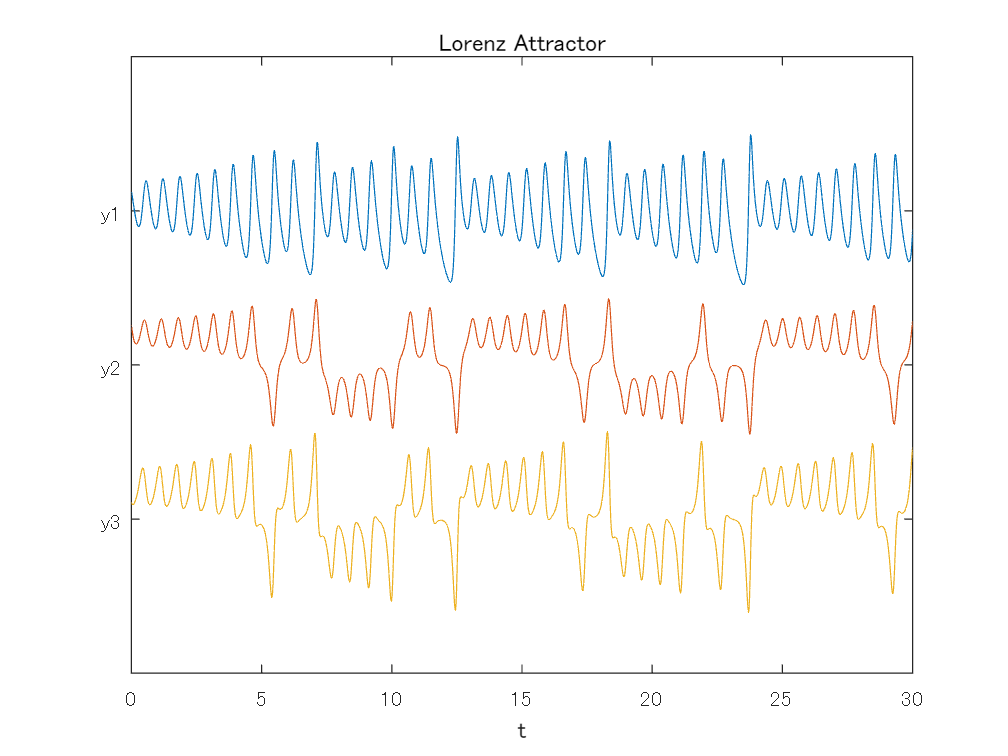

plot(t,[y(:,1)+15 y(:,2) y(:,3)-40]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'y3','y2','y1'})
xlabel('t')
title('Lorenz Attractor')

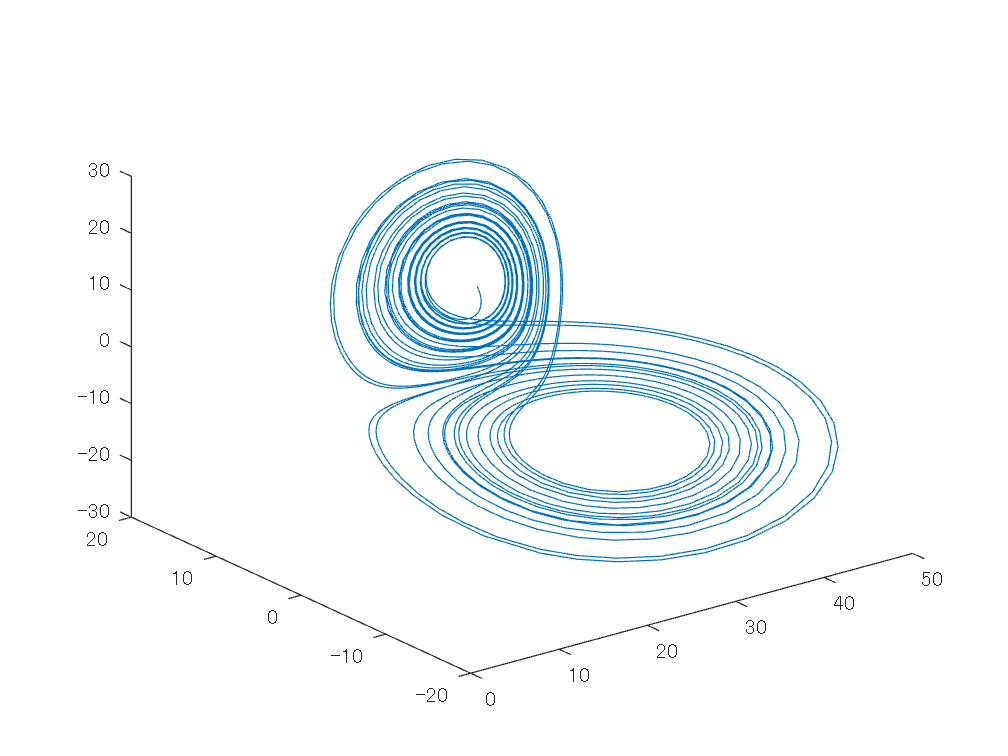


figure
h1 = plot3(y(:,1),y(:,2),y(:,3));

遅延埋め込みとデータ行列生成

nDelay = 1;

ts = [];
for iCol = 1:size(y,2)
    c = y(1:nDelay+1,iCol);
    r = y(nDelay+1:end,iCol);
    h = hankel(c,r);
    ts = cat(3,ts,h);
end

X = reshape(permute(ts,[2 1 3]),size(ts,2),[]);


学習方法

- ` Classify `$\{\mathbf{x}_k\}_k\in\mathcal{M}$` into `$Q$`-clusters by using Gaussian mixture model (GMM), where the dimension is reduced if possible.`

- ` Set `$\{\hat{\mathbf{a}}_c\}_c\mathcal{M}$` by the mean vectors `$\{\mathbf{\mu}_c\}_c$` of the `$c$`-th Gaussian obtained by Step~1.`

- ` Design analysis LSUNs `$\{\hat{\mathbf{\Psi}}_c\}_c$` from `$\{\mathbf{x}_k\}_k$`.`

- ` Obtain linear operators `$\{\hat{\mathbf{K}}_c\}_c$` and biases `$\{\hat{\mathbf{b}}_c\}_c$` from `$\{\mathbf{x}_k\}_k$` by using linear AEs with LSUN.`

Step 1 クラスタリング

nGauss = 4;
options = statset('MaxIter',1000);

Sigma = 'full';
SharedCovariance = false;

gmfit = fitgmdist(X,nGauss,'CovarianceType',Sigma, ...
    'SharedCovariance',SharedCovariance,'Options',options); % Fitted GMM
clusterX = cluster(gmfit,X); % Cluster index
if nDelay == 0
    hold on
    plot3(gmfit.mu(:,1),gmfit.mu(:,2),gmfit.mu(:,3),'kx','LineWidth',2,'MarkerSize',10)
end
hold off

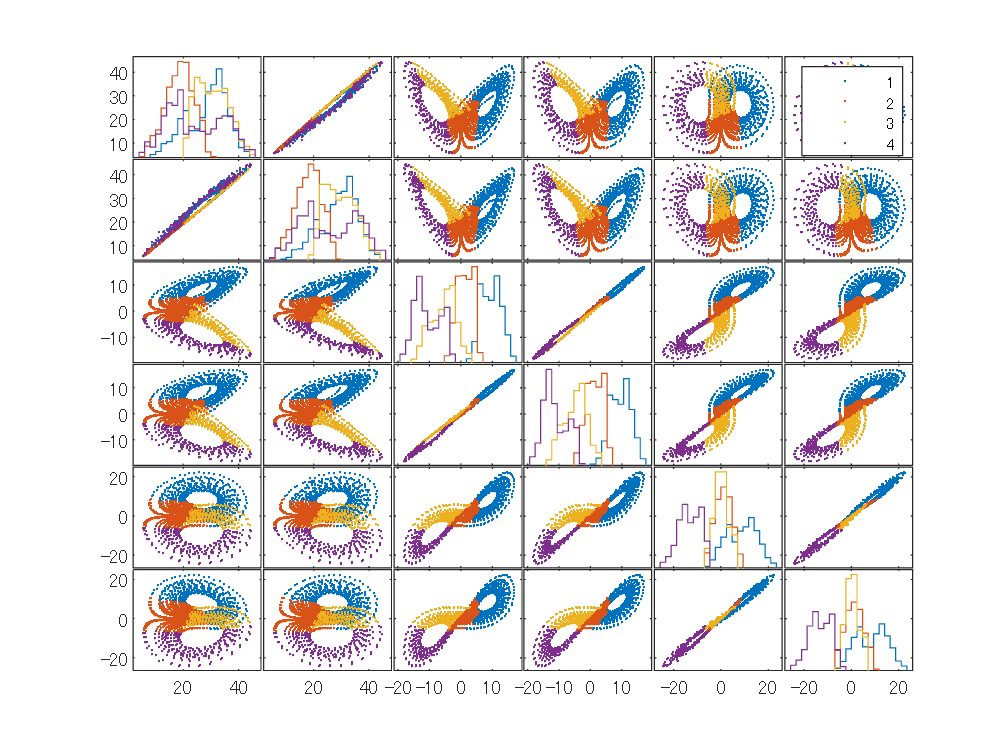


figure
gplotmatrix(X,[],clusterX)

Step 2 平均ベクトルの算出

ac = gmfit.mu % Q x 3(d+1)

ac =    28.4769   28.9357    9.6560    9.6069    8.8410    8.5328
   18.6628   18.0331    1.3951    1.3754    1.0822    1.2517
   30.5454   29.4857   -5.5120   -4.7693    0.0791    0.4536
   24.5059   25.9870  -10.5945  -11.1127  -13.2825  -13.2301


Step 3 PCA (LSUN) の設計

for c = 1:nGauss
    c
    Sigmac = gmfit.Sigma(:,:,c);
    Psi(:,:,c) = pcacov(Sigmac); % pca(Zc);
end

c = 1

c = 2

c = 3

c = 4

%plotmatrix(Zc)
%plotmatrix((Psi(:,:,c)*Zc.').')


Step 4 線形変換 Pc とバイアス bc の導出

P = 2; % # of channels
for c = 1:nGauss
    Ic = find(clusterX == c);
    Ic = Ic(1:end-1);
    %
    X0cT = X(Ic,:);
    X1cT = X(Ic+1,:);
    Z0cT = X0cT-ac(c,:);
    %
    Psic = Psi(:,:,c);
    PsiZ0c = Psi(:,:,c)*Z0cT.';
    SPsiZ0c = PsiZ0c(1:P,:);
    Q_bc = (X1cT).'*pinv([SPsiZ0c; ones(1,size(SPsiZ0c,2))]);
    %
    Qc = Q_bc(:,1:end-1);
    bc(:,c) = Q_bc(:,end);
    %
    Pc(:,:,c) = Psic(1:P,:)*Qc;
end

学習パラメータ

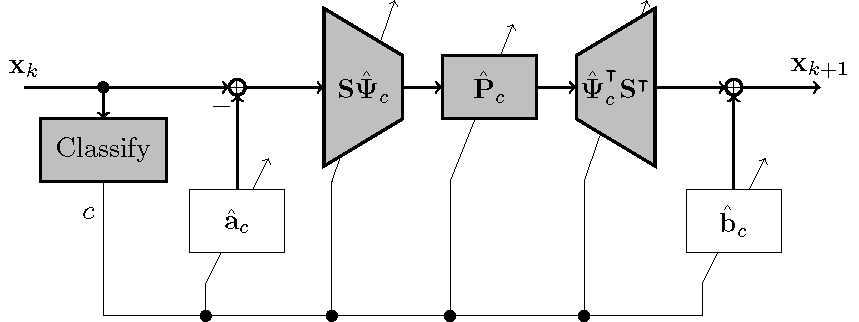


$$\mathbf{S}\hat{\mathbf{\Psi}}_c$$


SPsic = Psi(1:P,:,:)

SPsic = SPsic(:,:,1) =

    0.6061    0.3102   -0.1164   -0.5502    0.3869   -0.2655
    0.5172    0.4155   -0.3210    0.5849   -0.2565    0.2209


SPsic(:,:,2) =

    0.6759   -0.2354   -0.0719    0.1743   -0.6677    0.0805
    0.6482   -0.2154   -0.1358   -0.1827    0.6890   -0.0827


SPsic(:,:,3) =

    0.5790    0.2881    0.1994   -0.3635   -0.4964    0.4044
    0.5742    0.2648    0.3772    0.2068    0.5499   -0.3357


SPsic(:,:,4) =

    0.6555    0.2070    0.2047   -0.0141   -0.6480   -0.2558
    0.6693    0.0356    0.2164    0.1078    0.6530    0.2568



$$\hat{\mathbf{P}}_c$$


Pc

Pc = Pc(:,:,1) =

    0.5405    0.3803
   -0.5884    1.4211


Pc(:,:,2) =

    1.0297   -0.0886
   -0.0620    1.0454


Pc(:,:,3) =

    0.9700   -0.0322
    0.0616    0.9858


Pc(:,:,4) =

    0.9754   -0.2239
    0.2021    1.0133



$$\hat{\mathbf{a}}_c$$


ac

ac =    28.4769   28.9357    9.6560    9.6069    8.8410    8.5328
   18.6628   18.0331    1.3951    1.3754    1.0822    1.2517
   30.5454   29.4857   -5.5120   -4.7693    0.0791    0.4536
   24.5059   25.9870  -10.5945  -11.1127  -13.2825  -13.2301



$$\hat{\mathbf{b}}_c$$


bc

bc =    28.9364   18.0306   29.4851   25.9823
   29.3441   17.4664   28.4201   27.4275
    9.6006    1.3729   -4.7709  -11.1004
    9.4977    1.3915   -4.0885  -11.5199
    8.5181    1.2492    0.4486  -13.2296
    8.1594    1.4507    0.6935  -13.0006


Classifier

classify = @(x) cluster(gmfit,x.')

classify = 値をもつ function_handle :
    @(x)cluster(gmfit,x.')


シミュレーション

function [t,y] = lorenzgen(params)

sigma = params.sigma;
beta = params.beta;
rho = params.rho;
eta = params.eta;

A = [ -beta 0 eta;
    0 -sigma sigma;
    -eta rho -1 ];
v0 = [rho-1 eta eta]';
y0 = v0 + [3 2 -4]';
tspan = [0 30];

[t,y] = ode45(@(t,y) lorenzeqn(t,y,A), tspan, y0);
end

function ydot = lorenzeqn(t,y,A)

A(1,3) = y(2);
A(3,1) = -y(2);
ydot = A*y;

end